## Experiment 2

close all
clear all
clc

syms u1 u2 u3 u4 u5 u6 u7 u8 u9 u10 u11 u12 u13 u14 u15 u16 u17 u18 u19 u20 u21 u22 u23 u24 u25 u26 u27 u28 u29 u30 u31 u32 


### 3 Double integrators in an environment with obstacles avoided by CBF

%Three robots + 2 static obstacles
syms b1 b2 b3 b4
u = [u1 u2 u3 u4 u5 u6 u7 u8 u9 u10 u11 u12].'; % of form x1;y1;x2;y2;...;xn;yn;vx1;vy1;vx2;vy2;...;vxm;vym
b = [b1 b2 b3 b4].';% of form x_obs1;y_obs1;x_obs2;y_obs2


[h,q] = experiment2_barrier_obstacles(u,b)

matlabFunction(h,q,'File','CBFthreeRobotsandStatObs',...
    'Vars',{u b})

ans = function_handle with value:
    @CBFthreeRobotsandStatObs


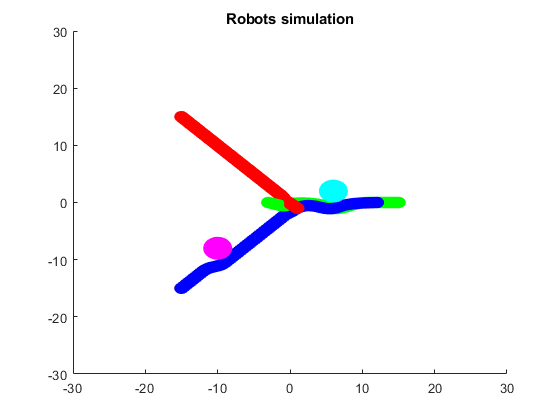

ans =   Simulink.SimulationOutput:

                   tout: [217x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


obstavoid = 'exp2_obstavoid';
open_system(obstavoid);
sim(obstavoid)

### Leader-follower: 3 Double integrators following a leader with CBF

%   FOUR ROBOTS
u = [u1 u2 u3 u4 u5 u6 u7 u8 u9 u10 u11 u12 u13 u14 u15 u16].'; % of form x1;y1;x2;y2;...;xn;yn;vx1;vy1;vx2;vy2;...;vxm;vym

[h,q,dP] = lf_barrier(u)

$$Vx = {u_{1}}^{2}+{u_{2}}^{2}+{u_{3}}^{2}+{u_{4}}^{2}+{u_{5}}^{2}+{u_{6}}^{2}+{u_{7}}^{2}+{u_{8}}^{2}+{u_{9}}^{2}+{u_{10}}^{2}+{u_{11}}^{2}+{u_{12}}^{2}+{u_{13}}^{2}+{u_{14}}^{2}+{u_{15}}^{2}+{u_{16}}^{2}$$

$$dVx = \left(\begin{array}{cccccccccccccccc} 2\,u_{1} & 2\,u_{2} & 2\,u_{3} & 2\,u_{4} & 2\,u_{5} & 2\,u_{6} & 2\,u_{7} & 2\,u_{8} & 2\,u_{9} & 2\,u_{10} & 2\,u_{11} & 2\,u_{12} & 2\,u_{13} & 2\,u_{14} & 2\,u_{15} & 2\,u_{16} \end{array}\right)$$

$$dP = \left(\begin{array}{c} \sqrt{{\left(u_{1}-u_{3}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{5}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{7}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{5}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{7}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{5}-u_{7}\right)}^{2}} \end{array}\right)$$

$$h = \begin{array}{l} \left(\begin{array}{c} 2\,\sqrt{10}\,\sqrt{\sigma_{6}-1}+\frac{\left(u_{1}-u_{3}\right)\,\left(u_{9}-u_{11}\right)+\left(u_{2}-u_{4}\right)\,\left(u_{10}-u_{12}\right)}{\sigma_{6}}\\ 2\,\sqrt{10}\,\sqrt{\sigma_{5}-1}+\frac{\left(u_{1}-u_{5}\right)\,\left(u_{9}-u_{13}\right)+\left(u_{2}-u_{6}\right)\,\left(u_{10}-u_{14}\right)}{\sigma_{5}}\\ 2\,\sqrt{10}\,\sqrt{\sigma_{4}-1}+\frac{\left(u_{1}-u_{7}\right)\,\left(u_{9}-u_{15}\right)+\left(u_{2}-u_{8}\right)\,\left(u_{10}-u_{16}\right)}{\sigma_{4}}\\ 2\,\sqrt{10}\,\sqrt{\sigma_{3}-1}+\frac{\left(u_{3}-u_{5}\right)\,\left(u_{11}-u_{13}\right)+\left(u_{4}-u_{6}\right)\,\left(u_{12}-u_{14}\right)}{\sigma_{3}}\\ 2\,\sqrt{10}\,\sqrt{\sigma_{2}-1}+\frac{\left(u_{3}-u_{7}\right)\,\left(u_{11}-u_{15}\right)+\left(u_{4}-u_{8}\right)\,\left(u_{12}-u_{16}\right)}{\sigma_{2}}\\ 2\,\sqrt{10}\,\sqrt{\sigma_{1}-1}+\frac{\left(u_{5}-u_{7}\right)\,\left(u_{13}-u_{15}\right)+\left(u_{6}-u_{8}\right)\,\left(u_{14}-u_{16}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left|u_{5}-u_{7}\right|}^{2}+{\left|u_{6}-u_{8}\right|}^{2}}\\ \sigma_{2}=\sqrt{{\left|u_{3}-u_{7}\right|}^{2}+{\left|u_{4}-u_{8}\right|}^{2}}\\ \sigma_{3}=\sqrt{{\left|u_{3}-u_{5}\right|}^{2}+{\left|u_{4}-u_{6}\right|}^{2}}\\ \sigma_{4}=\sqrt{{\left|u_{1}-u_{7}\right|}^{2}+{\left|u_{2}-u_{8}\right|}^{2}}\\ \sigma_{5}=\sqrt{{\left|u_{1}-u_{5}\right|}^{2}+{\left|u_{2}-u_{6}\right|}^{2}}\\ \sigma_{6}=\sqrt{{\left|u_{1}-u_{3}\right|}^{2}+{\left|u_{2}-u_{4}\right|}^{2}} \end{array}$$

$$dP = \left(\begin{array}{c} \sqrt{{\left(u_{1}-u_{3}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{5}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{7}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{5}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{7}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{5}-u_{7}\right)}^{2}} \end{array}\right)$$

matlabFunction(h,q,dP,'File','CBFlfRobots',...
    'Vars',u)

ans = function_handle with value:
    @CBFlfRobots


leaderfollower = 'leaderfollower';
open_system(leaderfollower);

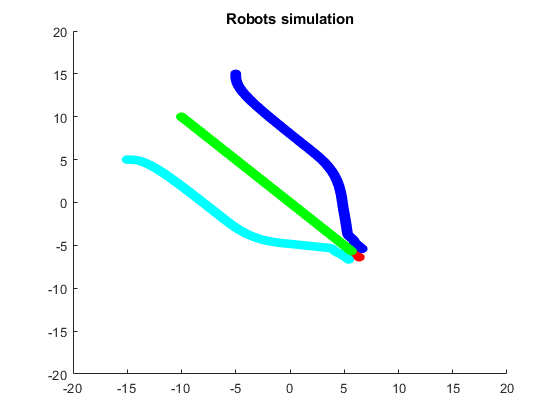

ans =   Simulink.SimulationOutput:

                   tout: [218x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim(leaderfollower)

## Leader-follower: 3 Double integrators following a leader in an environment with obstacles using CBF

%   FOUR ROBOTS
u = [u1 u2 u3 u4 u5 u6 u7 u8 u9 u10 u11 u12 u13 u14 u15 u16].'; % of form x1;y1;x2;y2;...;xn;yn;vx1;vy1;vx2;vy2;...;vxm;vym
syms b1 b2 b3 b4
b = [b1 b2 b3 b4].';% of form x_obs1;y_obs1;x_obs2;y_obs2
[h,q,dP] = lfobs_barrier(u,b)

$$Vx = {u_{1}}^{2}+{u_{2}}^{2}+{u_{3}}^{2}+{u_{4}}^{2}+{u_{5}}^{2}+{u_{6}}^{2}+{u_{7}}^{2}+{u_{8}}^{2}+{u_{9}}^{2}+{u_{10}}^{2}+{u_{11}}^{2}+{u_{12}}^{2}+{u_{13}}^{2}+{u_{14}}^{2}+{u_{15}}^{2}+{u_{16}}^{2}$$

$$dVx = \left(\begin{array}{cccccccccccccccc} 2\,u_{1} & 2\,u_{2} & 2\,u_{3} & 2\,u_{4} & 2\,u_{5} & 2\,u_{6} & 2\,u_{7} & 2\,u_{8} & 2\,u_{9} & 2\,u_{10} & 2\,u_{11} & 2\,u_{12} & 2\,u_{13} & 2\,u_{14} & 2\,u_{15} & 2\,u_{16} \end{array}\right)$$

$$dP = \left(\begin{array}{c} \sqrt{{\left(u_{1}-u_{3}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{5}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{7}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{5}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{7}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{5}-u_{7}\right)}^{2}} \end{array}\right)$$

$$dP = \left(\begin{array}{c} \sqrt{{\left(u_{1}-u_{3}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{5}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{1}-u_{7}\right)}^{2}+{\left(u_{2}-u_{6}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{5}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{3}-u_{7}\right)}^{2}}\\ \sqrt{{\left(u_{2}-u_{6}\right)}^{2}+{\left(u_{5}-u_{7}\right)}^{2}} \end{array}\right)$$

matlabFunction(h,q,dP,'File','CBFlfRobotsobs',...
    'Vars',{u b})

ans = function_handle with value:
    @CBFlfRobotsobs


leaderfollowerobs = 'leaderfollowerobs';
open_system(leaderfollowerobs);

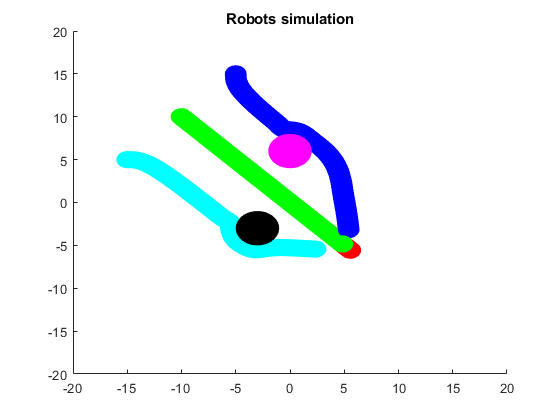

ans =   Simulink.SimulationOutput:

                   tout: [126x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim(leaderfollowerobs)